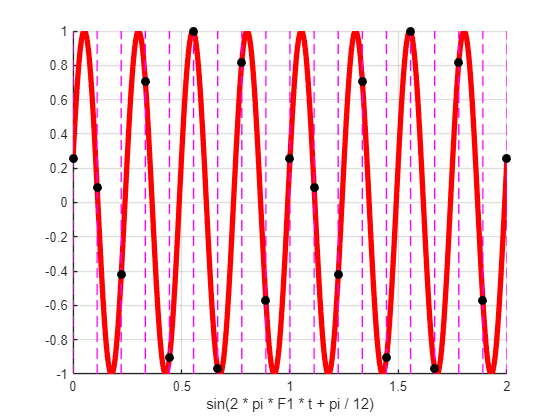

figure(1);
t = linspace(0, 2, 1001);
F1 = 4;
X1 = sin(2 * pi * F1 * t + pi / 12);
line(t, X1, 'LineWidth', 4, 'Color', 'r');
xlim([0 2]);
ylim([-1 1]);
xlabel("sin(2 * pi * F1 * t + pi / 12)");
FS = 9;
TS = 1/FS;
n=0:20;
t=n*TS;
Xn = sin(2 * pi * F1 * t + pi / 12);
for n=0:20
    line(n*TS*[1 1],[-1 1],'Color','m','LineWidth',1,'LineStyle','--');
    line(n*TS,Xn(n+1),'Color','k','Marker','.','Markersize',20);
end
grid on

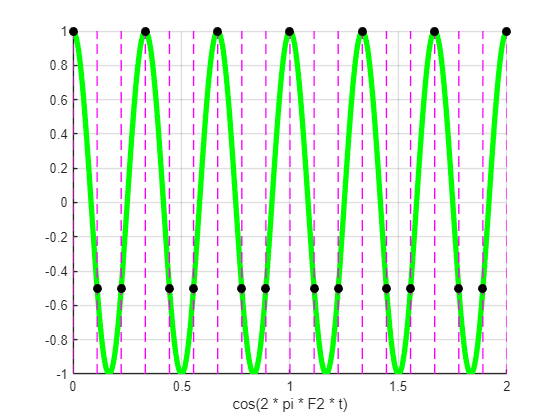

%------------------------------------------
figure(2);
t = linspace(0, 2, 1001);
F2 = 3;
X2 = cos(2 * pi * F2 * t);
line(t, X2, 'LineWidth', 4, 'Color', 'g');
xlim([0 2]);
ylim([-1 1]);
xlabel("cos(2 * pi * F2 * t)");
FS = 9;
TS = 1/FS;
n=0:20;
t=n*TS;
Xn = cos(2 * pi * F2 * t);
for n=0:20
    line(n*TS*[1 1],[-1 1],'Color','m','LineWidth',1,'LineStyle','--');
    line(n*TS,Xn(n+1),'Color','k','Marker','.','Markersize',20);
end
grid on

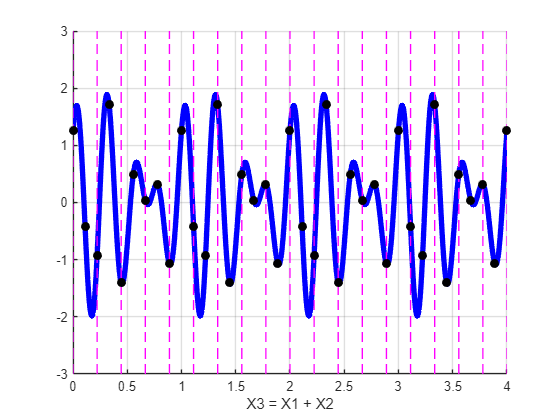

%------------------------------------------
figure(3);
t = linspace(0, 4, 1001);
X1 = sin(2 * pi * F1 * t + pi / 12);
X2 = cos(2 * pi * F2 * t);
X3 = X1 + X2;
line(t, X3, 'LineWidth', 4, 'Color', 'b');
xlim([0 4]);
ylim([-3 3]);
xlabel("X3 = X1 + X2");
FS = 9;
TS = 1/FS;
n=0:40;
t=n*TS;
X1 = sin(2 * pi * F1 * t + pi / 12);
X2 = cos(2 * pi * F2 * t);
Xn = X1+X2;
for n=0:40
    line(n*TS*[2 2],[-3 3],'Color','m','LineWidth',1,'LineStyle','--');
    line(n*TS,Xn(n+1),'Color','k','Marker','.','Markersize',20);
end
grid on

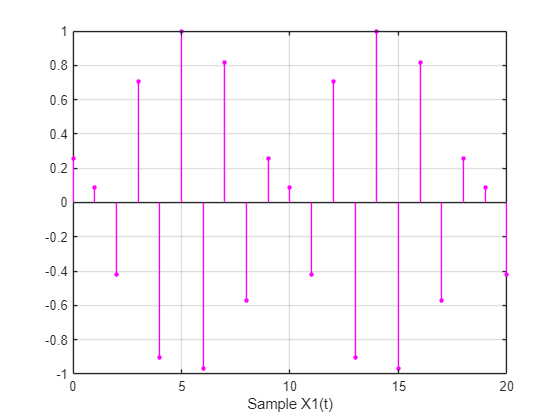

%------------------------------------------
figure(4);
FS = 9;
TS = 1/FS;
n = 0:20;
t =n*TS;
X1n = sin(2 * pi * F1 * t + pi / 12);
stem(n, X1n,'Color','m','Marker','.','MarkerSize',10);
xlim([0 20]);
xlabel("Sample X1(t)");
grid on

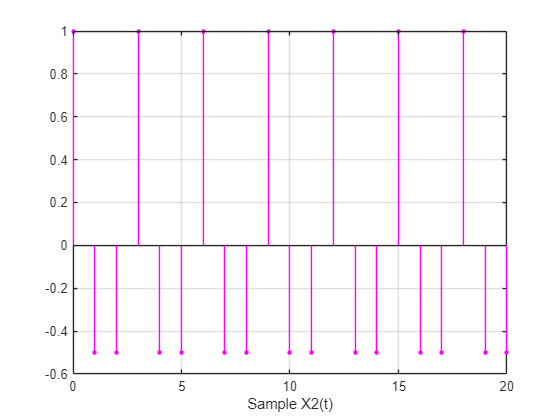

figure(5);
X2n = cos(2 * pi * F2 * t);
stem(n, X2n,'Color','m','Marker','.','MarkerSize',10);
xlim([0 20]);
xlabel("Sample X2(t)");
grid on

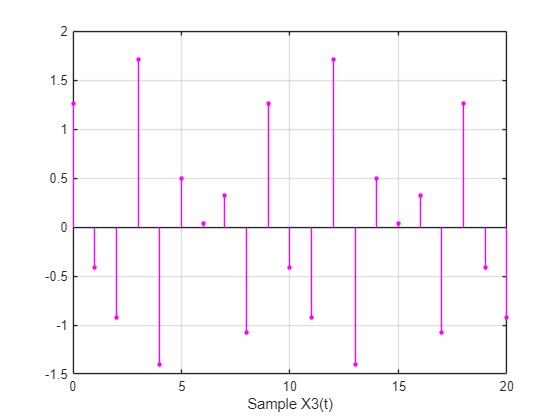

figure(6);
X3n = X1n + X2n;
stem(n, X3n,'Color','m','Marker','.','MarkerSize',10);
xlim([0 20]);
xlabel("Sample X3(t)");
grid on